## General

clearvars
abc = 'acegbdfh';
pi2.PC = 0.1081;
pi2.EM = 0.0122;
sympref('FloatingPointOutput',false);
syms r_1(x,y) r_2(x,y)
m  = sym('m',[1 2],'positive');
mu = sym('mu',[1 2],'positive');
WW  = sym('Omega','positive');
x  = sym('x','real');
y  = sym('y','real');
R  = [x;y];
r12 = sym('r_12','positive');
assume(r12~=0);
xi = sym('xi','real');
psi = sym('psi','real');
pp = sym('pi',[1 2],'positive');
vx = sym('x_dot','real');
vy = sym('y_dot','real');
V  = [vx;vy];
v  = norm(V)

$$v = \sqrt{{\left|\dot{x}\right|}^{2}+{\left|\dot{y}\right|}^{2}}$$

ww = sym('omega');
xx = sym('x',[1 2],'real');
yy = sym('y',[1 2],'real');
assumeAlso(xx(1)<0 & xx(2)>0);
RR  = [xx;yy];

V = -(mu(1)/r_1 + mu(2)/r_2)

$$V(x, y) = -\frac{\mu_{1}}{r_{1}\left(x,y\right)}-\frac{\mu_{2}}{r_{2}\left(x,y\right)}$$

Uw = WW^2*(x^2+y^2)/2;
U = -Uw + V

$$U(x, y) = -\frac{\Omega^{2}\,\left(x^{2}+y^{2}\right)}{2}-\frac{\mu_{1}}{r_{1}\left(x,y\right)}-\frac{\mu_{2}}{r_{2}\left(x,y\right)}$$

dU = gradient(U(x,y),[x,y])

$$dU = \left(\begin{array}{c} \frac{\mu_{1}\,\frac{\partial }{\partial x}r_{1}\left(x,y\right)}{{r_{1}\left(x,y\right)}^{2}}-\Omega^{2}\,x+\frac{\mu_{2}\,\frac{\partial }{\partial x}r_{2}\left(x,y\right)}{{r_{2}\left(x,y\right)}^{2}}\\ \frac{\mu_{1}\,\frac{\partial }{\partial y}r_{1}\left(x,y\right)}{{r_{1}\left(x,y\right)}^{2}}-\Omega^{2}\,y+\frac{\mu_{2}\,\frac{\partial }{\partial y}r_{2}\left(x,y\right)}{{r_{2}\left(x,y\right)}^{2}} \end{array}\right)$$

HU = collect(hessian(U(x,y),[x,y]),mu)

dU = subs(dU,{diff(r_1,x),diff(r_1,y),diff(r_2,x),diff(r_2,y)} , {(x-xx(1))/r_1,(y-yy(1))/r_1,(x-xx(2))/r_2,(y-yy(2))/r_2})

$$dU = \left(\begin{array}{c} \frac{\mu_{1}\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{3}}-\Omega^{2}\,x+\frac{\mu_{2}\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{3}}\\ \frac{\mu_{1}\,\left(y-y_{1}\right)}{{r_{1}\left(x,y\right)}^{3}}-\Omega^{2}\,y+\frac{\mu_{2}\,\left(y-y_{2}\right)}{{r_{2}\left(x,y\right)}^{3}} \end{array}\right)$$

HU = subs(HU,{diff(r_1,x),diff(r_1,y),diff(r_2,x),diff(r_2,y)} , {(x-xx(1))/r_1,(y-yy(1))/r_1,(x-xx(2))/r_2,(y-yy(2))/r_2});
HU = simplify(collect(subs(HU,{diff(r_1,x),diff(r_1,y),diff(r_2,x),diff(r_2,y)} , {(x-xx(1))/r_1,(y-yy(1))/r_1,(x-xx(2))/r_2,(y-yy(2))/r_2}),[1/r_1,1/r_2]),'IgnoreAnalyticConstraints',true)

$$HU = \left(\begin{array}{cc} \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,\left(x-x_{1}\right)\,\left(y-y_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,\left(x-x_{2}\right)\,\left(y-y_{2}\right)}{{r_{2}\left(x,y\right)}^{5}}\\ -\frac{3\,\mu_{1}\,\left(x-x_{1}\right)\,\left(y-y_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,\left(x-x_{2}\right)\,\left(y-y_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(y-y_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(y-y_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} \end{array}\right)$$

Assume $y_1=y_2=0$ and recall (but dont use) $x_1=-\frac{\mu_2}{\mu_1+\mu_2}r_{12}=-\pi_2r_{12}$ and $x_2=+\frac{\mu_1}{\mu_1+\mu_2}r_{12}=+\pi_1r_{12}$

%IU = subs(U,{r_1,r_2} , {sqrt((x-xx(1))^2+(y-yy(1))^2),sqrt((x-xx(2))^2+(y-yy(2))^2)})
dU = subs(dU,{yy(1),yy(2)},{0,0})

$$dU = \left(\begin{array}{c} \frac{\mu_{1}\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{3}}-\Omega^{2}\,x+\frac{\mu_{2}\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{3}}\\ \frac{\mu_{1}\,y}{{r_{1}\left(x,y\right)}^{3}}-\Omega^{2}\,y+\frac{\mu_{2}\,y}{{r_{2}\left(x,y\right)}^{3}} \end{array}\right)$$

HU = subs(HU,{yy(1),yy(2)},{0,0})

$$HU = \left(\begin{array}{cc} \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}}\\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y^{2}}{{r_{2}\left(x,y\right)}^{5}} \end{array}\right)$$

A = [0 0 1 0; 0 0 0 1; HU(1,1:2) 0 2*WW; HU(2,1:2) -2*WW 0]

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & 0 & 2\,\Omega \\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y^{2}}{{r_{2}\left(x,y\right)}^{5}} & -2\,\Omega & 0 \end{array}\right)$$

A = subs(A,{yy(1),yy(2)},{0,0})

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & 0 & 2\,\Omega \\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y^{2}}{{r_{2}\left(x,y\right)}^{5}} & -2\,\Omega & 0 \end{array}\right)$$

## U

disp(U)

$$-\frac{\Omega^{2}\,\left(x^{2}+y^{2}\right)}{2}-\frac{\mu_{1}}{r_{1}\left(x,y\right)}-\frac{\mu_{2}}{r_{2}\left(x,y\right)}$$

IU = subs(U,{r_1,r_2} , {sqrt((x-xx(1))^2+(y-yy(1))^2),sqrt((x-xx(2))^2+(y-yy(2))^2)})

$$IU(x, y) = -\frac{\Omega^{2}\,\left(x^{2}+y^{2}\right)}{2}-\frac{\mu_{1}}{\sqrt{{\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}}}-\frac{\mu_{2}}{\sqrt{{\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}}}$$

IU = subs(IU,{yy(1),yy(2)},{0,0})

$$IU(x, y) = -\frac{\Omega^{2}\,\left(x^{2}+y^{2}\right)}{2}-\frac{\mu_{1}}{\sqrt{{\left(x-x_{1}\right)}^{2}+y^{2}}}-\frac{\mu_{2}}{\sqrt{{\left(x-x_{2}\right)}^{2}+y^{2}}}$$

IU = subs(IU,{x,y,xx(1),xx(2)},{xi*r12,psi*r12,-pp(2)*r12,pp(1)*r12})

$$IU(x, y) = -\frac{\Omega^{2}\,\left(\psi^{2}\,{r_{12}}^{2}+{r_{12}}^{2}\,\xi^{2}\right)}{2}-\frac{\mu_{1}}{\sqrt{\psi^{2}\,{r_{12}}^{2}+{\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}}}-\frac{\mu_{2}}{\sqrt{\psi^{2}\,{r_{12}}^{2}+{\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}}}$$

IU = subs(IU,WW^2,(mu(1)+mu(2))/r12^3)

$$IU(x, y) = -\frac{\mu_{1}}{\sqrt{\psi^{2}\,{r_{12}}^{2}+{\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}}}-\frac{\mu_{2}}{\sqrt{\psi^{2}\,{r_{12}}^{2}+{\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}}}-\frac{\left(\mu_{1}+\mu_{2}\right)\,\left(\psi^{2}\,{r_{12}}^{2}+{r_{12}}^{2}\,\xi^{2}\right)}{2\,{r_{12}}^{3}}$$

IU = subs(IU,{mu(1),mu(2)},{pp(1)*(mu(1)+mu(2)),pp(2)*(mu(1)+mu(2))});
IU = simplify(collect(subs(IU,mu(1)+mu(2),WW^2*r12^3),WW^2));
IU = subs(IU,r12,1)*r12^2

$$IU(x, y) = -\Omega^{2}\,{r_{12}}^{2}\,\left(\frac{\pi_{1}}{\sqrt{{\left(\pi_{2}+\xi \right)}^{2}+\psi^{2}}}+\frac{\pi_{2}}{\sqrt{{\left(\pi_{1}-\xi \right)}^{2}+\psi^{2}}}+\frac{\left(\psi^{2}+\xi^{2}\right)\,\left(\pi_{1}+\pi_{2}\right)}{2}\right)$$

IU = subs(IU,pp(1),1-pp(2))

$$IU(x, y) = -\Omega^{2}\,{r_{12}}^{2}\,\left(\frac{\pi_{2}}{\sqrt{{\left(\pi_{2}+\xi -1\right)}^{2}+\psi^{2}}}-\frac{\pi_{2}-1}{\sqrt{{\left(\pi_{2}+\xi \right)}^{2}+\psi^{2}}}+\frac{\psi^{2}}{2}+\frac{\xi^{2}}{2}\right)$$

## L4, L5

$r_1=r_2=r_{12}$ & $\Omega^2=\frac{\mu_1+\mu_2}{r_{12}^3}$

dUV = simplify(subs(dU,{WW^2,r_1,r_2},{(mu(1)+mu(2))/r12^3,r12,r12}))

$$dUV = \left(\begin{array}{c} -\frac{\mu_{1}\,x_{1}+\mu_{2}\,x_{2}}{{r_{12}}^{3}}\\ 0 \end{array}\right)$$

Use  $x_1=-\frac{\mu_2}{\mu_1+\mu_2}r_{12}=-\pi_2r_{12}$ and $x_2=+\frac{\mu_1}{\mu_1+\mu_2}r_{12}=+\pi_1r_{12}$

dUV = subs(dUV,mu(1)*xx(1)+mu(2)*xx(2),0)

$$dUV = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

disp(HU)

$$\left(\begin{array}{cc} \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}}\\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y^{2}}{{r_{2}\left(x,y\right)}^{5}} \end{array}\right)$$

HV = collect(subs(HU,{WW^2,r_1,r_2},{(mu(1)+mu(2))/r12^3,r12,r12}),mu)

$$HV = \left(\begin{array}{cc} \left(-\frac{3\,{\left(x-x_{1}\right)}^{2}}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,{\left(x-x_{2}\right)}^{2}}{{r_{12}}^{5}}\right)\,\mu_{2} & \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2}\\ \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2} & \left(-\frac{3\,y^{2}}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y^{2}}{{r_{12}}^{5}}\right)\,\mu_{2} \end{array}\right)$$

HV(1,1) = collect(subs(HV(1,1),1/r12^3,WW^2/(mu(1)+mu(2))),[x-xx(1) x-xx(2) y])

$$HV = \left(\begin{array}{cc} \left(-\frac{3\,\mu_{1}}{{r_{12}}^{5}}\right)\,{\left(x-x_{1}\right)}^{2}+\left(-\frac{3\,\mu_{2}}{{r_{12}}^{5}}\right)\,{\left(x-x_{2}\right)}^{2} & \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2}\\ \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2} & \left(-\frac{3\,y^{2}}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y^{2}}{{r_{12}}^{5}}\right)\,\mu_{2} \end{array}\right)$$

HV(2,2) = collect(simplify(HV(2,2)),y)

$$HV = \left(\begin{array}{cc} \left(-\frac{3\,\mu_{1}}{{r_{12}}^{5}}\right)\,{\left(x-x_{1}\right)}^{2}+\left(-\frac{3\,\mu_{2}}{{r_{12}}^{5}}\right)\,{\left(x-x_{2}\right)}^{2} & \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2}\\ \left(-\frac{3\,y\,\left(x-x_{1}\right)}{{r_{12}}^{5}}\right)\,\mu_{1}+\left(-\frac{3\,y\,\left(x-x_{2}\right)}{{r_{12}}^{5}}\right)\,\mu_{2} & \left(-\frac{3\,\left(\mu_{1}+\mu_{2}\right)}{{r_{12}}^{5}}\right)\,y^{2} \end{array}\right)$$

x1 = -mu(2)/(mu(1)+mu(2))*r12

$$x1 = -\frac{\mu_{2}\,r_{12}}{\mu_{1}+\mu_{2}}$$

x2 = mu(1)/(mu(1)+mu(2))*r12

$$x2 = \frac{\mu_{1}\,r_{12}}{\mu_{1}+\mu_{2}}$$

### L4

eqs = [r_1==sqrt((x-xx(1))^2+(y)^2);r_2 ==sqrt((x-xx(2))^2+(y)^2)]

$$eqs(x, y) = \left(\begin{array}{c} r_{1}\left(x,y\right)=\sqrt{{\left(x-x_{1}\right)}^{2}+y^{2}}\\ r_{2}\left(x,y\right)=\sqrt{{\left(x-x_{2}\right)}^{2}+y^{2}} \end{array}\right)$$

eqs = subs(eqs,{r_1,r_2,xx(1),xx(2)},{r12,r12,-pp(2)*r12,pp(1)*r12})

$$eqs(x, y) = \left(\begin{array}{c} r_{12}=\sqrt{{\left(x+\pi_{2}\,r_{12}\right)}^{2}+y^{2}}\\ r_{12}=\sqrt{{\left(x-\pi_{1}\,r_{12}\right)}^{2}+y^{2}} \end{array}\right)$$

sols = solve(eqs)

sols = struct with fields:
    x: [0×1 sym]
    y: [0×1 sym]


sols = subs(sols,pp(1),1-pp(2))

sols = struct with fields:
    x: [0×1 sym]
    y: [0×1 sym]


collect(sols.x,r12)

 
ans =
 
Empty sym: 0-by-1
 


sols.y

 
ans =
 
Empty sym: 0-by-1
 


xo = simplify(r12/2-mu(2)/(mu(1)+mu(2))*r12)

$$xo = \frac{r_{12}\,\left(\mu_{1}-\mu_{2}\right)}{2\,\left(\mu_{1}+\mu_{2}\right)}$$

yo = sqrt(3)/2*r12

$$yo = \frac{\sqrt{3}\,r_{12}}{2}$$

#### HU

Use $x_1=-\frac{\mu_2}{\mu_1+\mu_2}r_{12}=-\pi_2r_{12}$ and $x_2=+\frac{\mu_1}{\mu_1+\mu_2}r_{12}=+\pi_1r_{12}$, $x_0=\frac{\mu_1-\mu_2}{\mu_1+\mu_2}\frac{r_{12}}{2}$ and $y_0=\frac{\sqrt{3}}{2}r_{12}$

HU4 = simplify(subs(HV,{x,y,xx(1),xx(2)},{xo,yo,x1,x2}))

$$HU4 = \left(\begin{array}{cc} -\frac{3\,\left(\mu_{1}+\mu_{2}\right)}{4\,{r_{12}}^{3}} & -\frac{\sqrt{3}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,{r_{12}}^{3}}\\ -\frac{\sqrt{3}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,{r_{12}}^{3}} & -\frac{9\,\left(\mu_{1}+\mu_{2}\right)}{4\,{r_{12}}^{3}} \end{array}\right)$$

Reintroduce $\Omega^2=\frac{\mu_1+\mu_2}{r_{12}^3}$

HU4 = subs(HU4,1/r12^3,WW^2/(mu(1)+mu(2)))

$$HU4 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & -\frac{\sqrt{3}\,\Omega^{2}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,\left(\mu_{1}+\mu_{2}\right)}\\ -\frac{\sqrt{3}\,\Omega^{2}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,\left(\mu_{1}+\mu_{2}\right)} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

Define $\pi_{1,2}=\frac{\mu_{1,2}}{\mu_1+\mu_2}$

HU4 = simplify(subs(HU4,{mu(1),mu(2)},{pp(1)*(mu(1)+mu(2)),pp(2)*(mu(1)+mu(2))}))

$$HU4 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(\pi_{1}-\pi_{2}\right)}{4\,\left(\pi_{1}+\pi_{2}\right)}\\ -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(\pi_{1}-\pi_{2}\right)}{4\,\left(\pi_{1}+\pi_{2}\right)} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

Note $\pi_1+\pi_2=1$

HU4 = subs(HU4,pp(1),1-pp(2))

$$HU4 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4}\\ \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

#### A

A4 = [0 0 1 0; 0 0 0 1; -HU4(1,1:2) 0 2*WW; -HU4(2,1:2) -2*WW 0]

$$A4 = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{3\,\Omega^{2}}{4} & -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & 0 & 2\,\Omega \\ -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & \frac{9\,\Omega^{2}}{4} & -2\,\Omega & 0 \end{array}\right)$$

ev4 = eig(A4)

$$ev4 = \left(\begin{array}{c} \sqrt{-\frac{\Omega^{2}}{2}-\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}}\\ \sqrt{\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}-\frac{\Omega^{2}}{2}}\\ -\sqrt{-\frac{\Omega^{2}}{2}-\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}}\\ -\sqrt{\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}-\frac{\Omega^{2}}{2}} \end{array}\right)$$

### L5

xo = simplify(r12/2-mu(2)/(mu(1)+mu(2))*r12)

$$xo = \frac{r_{12}\,\left(\mu_{1}-\mu_{2}\right)}{2\,\left(\mu_{1}+\mu_{2}\right)}$$

yo = -sqrt(3)/2*r12

$$yo = -\frac{\sqrt{3}\,r_{12}}{2}$$

#### HU

Use $x_1=-\frac{\mu_2}{\mu_1+\mu_2}r_{12}=-\pi_2r_{12}$ and $x_2=+\frac{\mu_1}{\mu_1+\mu_2}r_{12}=+\pi_1r_{12}$, $x_0=\frac{\mu_1-\mu_2}{\mu_1+\mu_2}\frac{r_{12}}{2}$ and $y_0=-\frac{\sqrt{3}}{2}r_{12}$

HU5 = simplify(subs(HV,{x,y,xx(1),xx(2)},{xo,yo,x1,x2}),'IgnoreAnalyticConstraints',true)

$$HU5 = \left(\begin{array}{cc} -\frac{3\,\left(\mu_{1}+\mu_{2}\right)}{4\,{r_{12}}^{3}} & \frac{\sqrt{3}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,{r_{12}}^{3}}\\ \frac{\sqrt{3}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,{r_{12}}^{3}} & -\frac{9\,\left(\mu_{1}+\mu_{2}\right)}{4\,{r_{12}}^{3}} \end{array}\right)$$

Reintroduce $\Omega^2=\frac{\mu_1+\mu_2}{r_{12}^3}$

HU5 = subs(HU5,1/r12^3,WW^2/(mu(1)+mu(2)))

$$HU5 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & \frac{\sqrt{3}\,\Omega^{2}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,\left(\mu_{1}+\mu_{2}\right)}\\ \frac{\sqrt{3}\,\Omega^{2}\,\left(3\,\mu_{1}-3\,\mu_{2}\right)}{4\,\left(\mu_{1}+\mu_{2}\right)} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

Define $\pi_{1,2}=\frac{\mu_{1,2}}{\mu_1+\mu_2}$

HU5 = simplify(subs(HU5,{mu(1),mu(2)},{pp(1)*sum(mu),pp(2)*sum(mu)}),'IgnoreAnalyticConstraints',true)

$$HU5 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(\pi_{1}-\pi_{2}\right)}{4\,\left(\pi_{1}+\pi_{2}\right)}\\ \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(\pi_{1}-\pi_{2}\right)}{4\,\left(\pi_{1}+\pi_{2}\right)} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

Note $\pi_1+\pi_2=1$

HU5 = subs(HU5,pp(1),1-pp(2))

$$HU5 = \left(\begin{array}{cc} -\frac{3\,\Omega^{2}}{4} & -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4}\\ -\frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & -\frac{9\,\Omega^{2}}{4} \end{array}\right)$$

#### A

A5 = [0 0 1 0; 0 0 0 1; -HU5(1,1:2) 0 2*WW; -HU5(2,1:2) -2*WW 0]

$$A5 = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{3\,\Omega^{2}}{4} & \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & 0 & 2\,\Omega \\ \frac{3\,\sqrt{3}\,\Omega^{2}\,\left(2\,\pi_{2}-1\right)}{4} & \frac{9\,\Omega^{2}}{4} & -2\,\Omega & 0 \end{array}\right)$$

ev5 = eig(A5)

$$ev5 = \left(\begin{array}{c} \sqrt{-\frac{\Omega^{2}}{2}-\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}}\\ \sqrt{\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}-\frac{\Omega^{2}}{2}}\\ -\sqrt{-\frac{\Omega^{2}}{2}-\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}}\\ -\sqrt{\frac{\Omega^{2}\,\sqrt{27\,{\pi_{2}}^{2}-27\,\pi_{2}+1}}{2}-\frac{\Omega^{2}}{2}} \end{array}\right)$$

evV = ev5;
lims = double(solve(27*pp(2)^2 - 27*pp(2) + 1==0,pp(2)))

lims =     0.0385
    0.9615


1/2*(1-sqrt(23/3)/3)

ans = 0.0385

var = vpa(ans)

$$var = 0.038520896504551371819502492144238$$

## L1, L2, L3

$r_1=\sqrt{(x-x_1)^2+(y-y_1)^2}$ & $r_2=\sqrt{(x-x_2)^2+(y-y_2)^2}$

### dU

dUI = simplify(subs(dU,{r_1,r_2},{sqrt((x-xx(1))^2+(y-yy(1))^2),sqrt((x-xx(2))^2+(y-yy(2))^2)}),'IgnoreAnalyticConstraints',true);


$$y_1=y_2=y=0$$


dUI = collect(subs(dUI,{y,yy(1),yy(2)},{0,0,0}),mu)

$$dUI = \left(\begin{array}{c} \frac{x-x_{1}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}\,\mu_{1}+\frac{x-x_{2}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}\,\mu_{2}-\Omega^{2}\,x\\ 0 \end{array}\right)$$

dUI=subs(dUI,{mu(1),mu(2)},{pp(1)*sum(mu),pp(2)*sum(mu)})

$$dUI = \left(\begin{array}{c} \frac{\pi_{1}\,\left(\mu_{1}+\mu_{2}\right)\,\left(x-x_{1}\right)}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\Omega^{2}\,x+\frac{\pi_{2}\,\left(\mu_{1}+\mu_{2}\right)\,\left(x-x_{2}\right)}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}\\ 0 \end{array}\right)$$

dUI = subs(dUI,mu(1)+mu(2),r12^3*WW^2)

$$dUI = \left(\begin{array}{c} \frac{\Omega^{2}\,\pi_{1}\,{r_{12}}^{3}\,\left(x-x_{1}\right)}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\Omega^{2}\,x+\frac{\Omega^{2}\,\pi_{2}\,{r_{12}}^{3}\,\left(x-x_{2}\right)}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}\\ 0 \end{array}\right)$$

dUI = subs(dUI,{x,xx(1),xx(2)},{xi*r12,-pp(2)*r12,+pp(1)*r12})

$$dUI = \left(\begin{array}{c} \frac{\Omega^{2}\,\pi_{1}\,{r_{12}}^{3}\,\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}{{\left({\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}\right)}^{3/2}}-\Omega^{2}\,r_{12}\,\xi -\frac{\Omega^{2}\,\pi_{2}\,{r_{12}}^{3}\,\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}{{\left({\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}\right)}^{3/2}}\\ 0 \end{array}\right)$$

dUI = collect(subs(dUI,{x,xx(1),xx(2)},{xi*r12,-pp(2)*r12,pp(1)*r12}),WW)

$$dUI = \left(\begin{array}{c} \left(\frac{\pi_{1}\,{r_{12}}^{3}\,\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}{{\left({\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}\right)}^{3/2}}-r_{12}\,\xi -\frac{\pi_{2}\,{r_{12}}^{3}\,\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}{{\left({\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}\right)}^{3/2}}\right)\,\Omega^{2}\\ 0 \end{array}\right)$$

dUI = subs(collect(subs(dUI,mu(1)+mu(2),r12^3*WW^2),WW^2),r12,1)

$$dUI = \left(\begin{array}{c} -\Omega^{2}\,\left(\xi -\frac{\pi_{1}\,\left(\pi_{2}+\xi \right)}{{\left({\left(\pi_{2}+\xi \right)}^{2}\right)}^{3/2}}+\frac{\pi_{2}\,\left(\pi_{1}-\xi \right)}{{\left({\left(\pi_{1}-\xi \right)}^{2}\right)}^{3/2}}\right)\\ 0 \end{array}\right)$$

dUI = simplify(subs(dUI,{(pp(2)+xi)^2,(pp(1)-xi)^2},{abs(pp(2)+xi)^2,abs(xi-pp(1))^2}))

$$dUI = \left(\begin{array}{c} -\Omega^{2}\,\left(\xi -\frac{\pi_{1}\,\left(\pi_{2}+\xi \right)}{{\left|\pi_{2}+\xi \right|}^{3}}+\frac{\pi_{2}\,\left(\pi_{1}-\xi \right)}{{\left|\pi_{1}-\xi \right|}^{3}}\right)\\ 0 \end{array}\right)$$

disp(-( (1-pp(2)).*(xi+pp(2))./abs(xi+pp(2)).^3 + pp(2).*(xi+pp(2)-1)./abs(xi+pp(2)-1).^3 - xi))

$$\xi -\frac{\pi_{2}\,\left(\pi_{2}+\xi -1\right)}{{\left|\pi_{2}+\xi -1\right|}^{3}}+\frac{\left(\pi_{2}+\xi \right)\,\left(\pi_{2}-1\right)}{{\left|\pi_{2}+\xi \right|}^{3}}$$

g = subs(-dUI(1)/WW^2,pp(1),1-pp(2))

$$g = \xi -\frac{\pi_{2}\,\left(\pi_{2}+\xi -1\right)}{{\left|\pi_{2}+\xi -1\right|}^{3}}+\frac{\left(\pi_{2}+\xi \right)\,\left(\pi_{2}-1\right)}{{\left|\pi_{2}+\xi \right|}^{3}}$$

g = matlabFunction(g)

g = function_handle with value:
    @(pi2,xi)xi-pi2.*1.0./abs(pi2+xi-1.0).^3.*(pi2+xi-1.0)+1.0./abs(pi2+xi).^3.*(pi2+xi).*(pi2-1.0)


eps = 1e-6;
p = linspace(0+eps,1-eps,10001);
for i = 1:length(p)
    L{3}.xi(i) = fzero(@(xi)g(p(i),xi),[-2 -p(i)-eps/10]);
    L{1}.xi(i) = fzero(@(xi)g(p(i),xi),[-p(i)+eps/10 1-p(i)-eps/10]);
    L{2}.xi(i) = fzero(@(xi)g(p(i),xi),[1-p(i)+eps/10 2]);
end
% clf
% figure;
% plot(p,L{1}.xi,'m',p,L{2}.xi,'b',p,L{3}.xi,'k');

tlo = tiledlayout(2,1);
ax = nexttile;
ax.XLim = [0 1];
ax.YLim = [min([min(L{1}.xi),min(L{2}.xi),min(L{3}.xi)]) max([max(L{1}.xi),max(L{2}.xi),max(L{3}.xi)])];
ax.TickDir = 'out';
ax.FontSize = 14;
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'off';
% ax.DataAspectRatio = [1 1 1];
% xlabel('\pi_2')
ax.XLabel = [];
% ax.XTickLabel = [];
ylabel('\xi')
hold(ax)

Current plot held


plot(ax,p,L{1}.xi,'Color',[0 .5 0],'DisplayName','L_1','LineWidth',1);
plot(ax,p,L{2}.xi,'r','DisplayName','L_2','LineWidth',1);
plot(ax,p,L{3}.xi,'b','DisplayName','L_3','LineWidth',1);
plot(ax,pi2.EM*[1 1],ax.YLim,'k-','DisplayName','Earth-Moon','LineWidth',1)
plot(ax,pi2.PC*[1 1],ax.YLim,'k-.','DisplayName','Pluto-Charon','LineWidth',1)
plot(ax,p,-p,'k--',p,1-p,'k--');
text(ax,ax.XLim(1),ax.YLim(1),{' ';'(a)  '},'HorizontalAlignment','right','VerticalAlignment','top','FontWeight','bold','FontSize',16);
% rectangle(ax,'Position',[ax.XLim(1),ax.YLim(1),lims(1)-ax.XLim(1),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);
% rectangle(ax,'Position',[lims(2),ax.YLim(1),ax.XLim(2)-lims(2),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);

ax.Box ="on";

ax = nexttile;
for i = 1:length(p)
    for n=1:3
        ksi = L{n}.xi(i);
        L{n}.bb(i) = p(i)/abs((p(i) + ksi - 1))^3 - (p(i) - 1)/abs((p(i) + ksi))^3;
    end
end
ax.XLim = [0 1];
ax.YLim = [min([min(L{1}.bb),min(L{2}.bb),min(L{3}.bb)]) max([max(L{1}.bb),max(L{2}.bb),max(L{3}.bb)])];
ax.TickDir = 'out';
ax.FontSize = 14;
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'off';
% ax.DataAspectRatio = [1 1 1];
xlabel('\pi_2')
ylabel('\beta')
hold(ax)

Current plot held


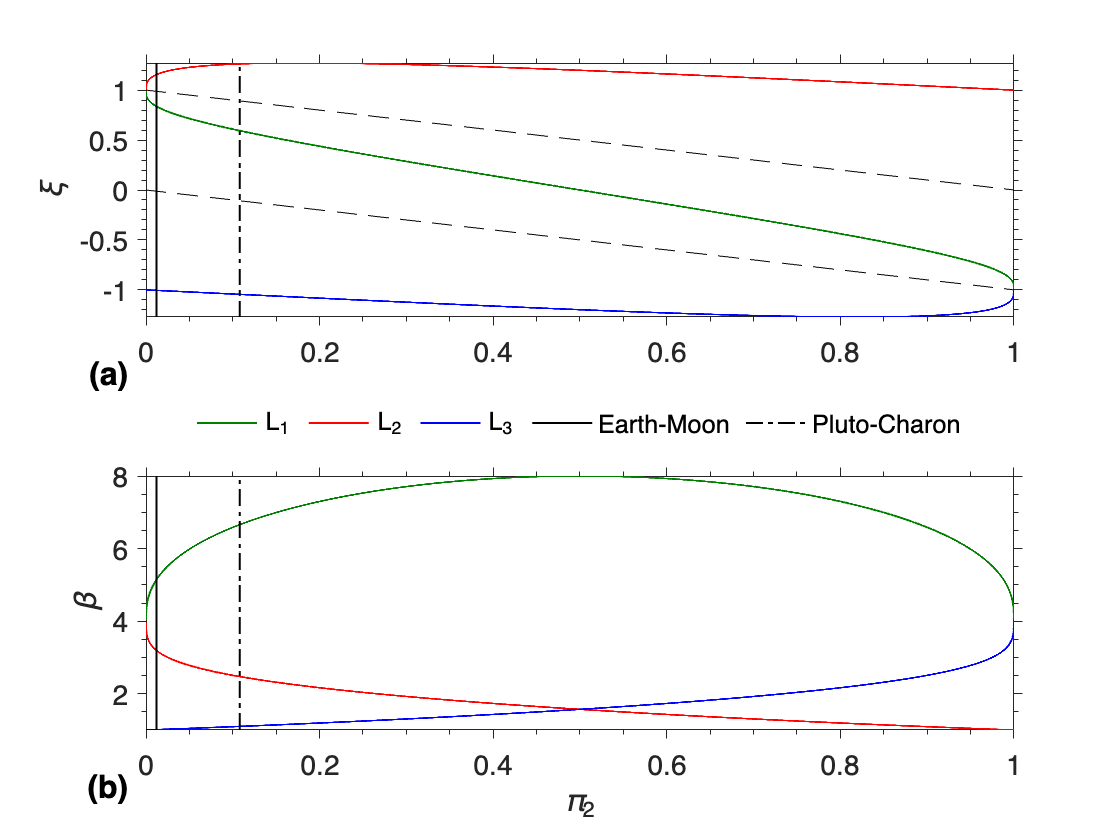

plot(ax,p,L{1}.bb,'Color',[0 .5 0],'DisplayName','L_1','LineWidth',1);
plot(ax,p,L{2}.bb,'r','DisplayName','L_2','LineWidth',1);
plot(ax,p,L{3}.bb,'b','DisplayName','L_3','LineWidth',1);
plot(ax,pi2.EM*[1 1],ax.YLim,'k-','DisplayName','Earth-Moon','LineWidth',1);
plot(ax,pi2.PC*[1 1],ax.YLim,'k-.','DisplayName','Pluto-Charon','LineWidth',1);
text(ax,ax.XLim(1),ax.YLim(1),{' ';'(b)  '},'HorizontalAlignment','right','VerticalAlignment','top','FontWeight','bold','FontSize',16);
lg = legend(ax);
lg.AutoUpdate ="off";
% rectangle(ax,'Position',[ax.XLim(1),ax.YLim(1),lims(1)-ax.XLim(1),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);
% rectangle(ax,'Position',[lims(2),ax.YLim(1),ax.XLim(2)-lims(2),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);
plot(ax,p,-p,'k--',p,1-p,'k--','LineWidth',1);
ax.Box ="on";
lg.Orientation = 'Horizontal';
lg.NumColumns = 5;
lg.Location = 'northoutside';
lg.Box = 'off';
exportgraphics(tlo,'xi_bb.pdf',...
    'ContentType','vector',...
    'BackgroundColor','none')

This is the S-curve equation.

### HU

disp(HU)

$$\left(\begin{array}{cc} \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{r_{2}\left(x,y\right)}^{5}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}}\\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{r_{2}\left(x,y\right)}^{5}} & \frac{\mu_{1}}{{r_{1}\left(x,y\right)}^{3}}+\frac{\mu_{2}}{{r_{2}\left(x,y\right)}^{3}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{r_{1}\left(x,y\right)}^{5}}-\frac{3\,\mu_{2}\,y^{2}}{{r_{2}\left(x,y\right)}^{5}} \end{array}\right)$$

HI = subs(HU,{r_1,r_2},{sqrt((x-xx(1))^2+(y-yy(1))^2),sqrt((x-xx(2))^2+(y-yy(2))^2)})

$$HI = \left(\begin{array}{cc} \frac{\mu_{1}}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{3/2}}+\frac{\mu_{2}}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{3/2}}-\Omega^{2}-\frac{3\,\mu_{1}\,{\left(x-x_{1}\right)}^{2}}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{5/2}}-\frac{3\,\mu_{2}\,{\left(x-x_{2}\right)}^{2}}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{5/2}} & -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{5/2}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{5/2}}\\ -\frac{3\,\mu_{1}\,y\,\left(x-x_{1}\right)}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{5/2}}-\frac{3\,\mu_{2}\,y\,\left(x-x_{2}\right)}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{5/2}} & \frac{\mu_{1}}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{3/2}}+\frac{\mu_{2}}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{3/2}}-\Omega^{2}-\frac{3\,\mu_{1}\,y^{2}}{{\left({\left(x-x_{1}\right)}^{2}+{\left(y-y_{1}\right)}^{2}\right)}^{5/2}}-\frac{3\,\mu_{2}\,y^{2}}{{\left({\left(x-x_{2}\right)}^{2}+{\left(y-y_{2}\right)}^{2}\right)}^{5/2}} \end{array}\right)$$


$$y_1=y_2=y=0$$


HI = collect(subs(HI,{y,yy(1),yy(2)},{0,0,0}),mu)

$$HI = \left(\begin{array}{cc} \left(\frac{1}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{1}\right)}^{2}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{5/2}}\right)\,\mu_{1}+\left(\frac{1}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{2}\right)}^{2}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{5/2}}\right)\,\mu_{2}-\Omega^{2} & 0\\ 0 & \frac{\mu_{1}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}+\frac{\mu_{2}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}-\Omega^{2} \end{array}\right)$$

HI=subs(HI,{mu(1),mu(2)},{pp(1)*(mu(1)+mu(2)),pp(2)*(mu(1)+mu(2))})

$$HI = \left(\begin{array}{cc} -\Omega^{2}+\pi_{1}\,\left(\mu_{1}+\mu_{2}\right)\,\left(\frac{1}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{1}\right)}^{2}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{5/2}}\right)+\pi_{2}\,\left(\mu_{1}+\mu_{2}\right)\,\left(\frac{1}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{2}\right)}^{2}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{5/2}}\right) & 0\\ 0 & \frac{\pi_{1}\,\left(\mu_{1}+\mu_{2}\right)}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\Omega^{2}+\frac{\pi_{2}\,\left(\mu_{1}+\mu_{2}\right)}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}} \end{array}\right)$$

HI = subs(HI,mu(1)+mu(2),r12^3*WW^2)

$$HI = \left(\begin{array}{cc} \Omega^{2}\,\pi_{1}\,{r_{12}}^{3}\,\left(\frac{1}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{1}\right)}^{2}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{5/2}}\right)-\Omega^{2}+\Omega^{2}\,\pi_{2}\,{r_{12}}^{3}\,\left(\frac{1}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(x-x_{2}\right)}^{2}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{5/2}}\right) & 0\\ 0 & \frac{\Omega^{2}\,\pi_{1}\,{r_{12}}^{3}}{{\left({\left(x-x_{1}\right)}^{2}\right)}^{3/2}}-\Omega^{2}+\frac{\Omega^{2}\,\pi_{2}\,{r_{12}}^{3}}{{\left({\left(x-x_{2}\right)}^{2}\right)}^{3/2}} \end{array}\right)$$

% xi = sym('xi','real');

HI = collect(subs(HI,{x,xx(1),xx(2)},{xi*r12,-pp(2)*r12,pp(1)*r12}),WW)

$$HI = \left(\begin{array}{cc} \left(-\pi_{1}\,{r_{12}}^{3}\,\left(\frac{3\,{\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}}{{\left({\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}\right)}^{5/2}}-\frac{1}{{\left({\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}\right)}^{3/2}}\right)-\pi_{2}\,{r_{12}}^{3}\,\left(\frac{3\,{\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}}{{\left({\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}\right)}^{5/2}}-\frac{1}{{\left({\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}\right)}^{3/2}}\right)-1\right)\,\Omega^{2} & 0\\ 0 & \left(\frac{\pi_{1}\,{r_{12}}^{3}}{{\left({\left(\pi_{2}\,r_{12}+r_{12}\,\xi \right)}^{2}\right)}^{3/2}}+\frac{\pi_{2}\,{r_{12}}^{3}}{{\left({\left(\pi_{1}\,r_{12}-r_{12}\,\xi \right)}^{2}\right)}^{3/2}}-1\right)\,\Omega^{2} \end{array}\right)$$

HI = subs(collect(subs(HI,mu(1)+mu(2),r12^3*WW^2),WW^2),r12,1)

$$HI = \left(\begin{array}{cc} \Omega^{2}\,\left(\pi_{1}\,\left(\frac{1}{{\left({\left(\pi_{2}+\xi \right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(\pi_{2}+\xi \right)}^{2}}{{\left({\left(\pi_{2}+\xi \right)}^{2}\right)}^{5/2}}\right)+\pi_{2}\,\left(\frac{1}{{\left({\left(\pi_{1}-\xi \right)}^{2}\right)}^{3/2}}-\frac{3\,{\left(\pi_{1}-\xi \right)}^{2}}{{\left({\left(\pi_{1}-\xi \right)}^{2}\right)}^{5/2}}\right)-1\right) & 0\\ 0 & \Omega^{2}\,\left(\frac{\pi_{2}}{{\left({\left(\pi_{1}-\xi \right)}^{2}\right)}^{3/2}}+\frac{\pi_{1}}{{\left({\left(\pi_{2}+\xi \right)}^{2}\right)}^{3/2}}-1\right) \end{array}\right)$$

bb = sym('beta');
HI = collect(simplify(subs(HI,{(pp(1)-xi)^2,(pp(2)-xi)^2,(pp(1)+xi)^2,(pp(2)+xi)^2}, {abs(xi-pp(1))^2,abs(xi-pp(2))^2,abs(xi+pp(1))^2,abs(xi+pp(2))^2})),pp)

$$HI = \left(\begin{array}{cc} \left(-\frac{2\,\Omega^{2}}{{\left|\pi_{2}+\xi \right|}^{3}}\right)\,\pi_{1}+\left(-\frac{2\,\Omega^{2}}{{\left|\pi_{1}-\xi \right|}^{3}}\right)\,\pi_{2}-\Omega^{2} & 0\\ 0 & \frac{\Omega^{2}}{{\left|\pi_{2}+\xi \right|}^{3}}\,\pi_{1}+\frac{\Omega^{2}}{{\left|\pi_{1}-\xi \right|}^{3}}\,\pi_{2}-\Omega^{2} \end{array}\right)$$

HI = collect(HI,WW)

$$HI = \left(\begin{array}{cc} \left(-\frac{2\,\pi_{2}}{{\left|\pi_{1}-\xi \right|}^{3}}-\frac{2\,\pi_{1}}{{\left|\pi_{2}+\xi \right|}^{3}}-1\right)\,\Omega^{2} & 0\\ 0 & \left(\frac{\pi_{2}}{{\left|\pi_{1}-\xi \right|}^{3}}+\frac{\pi_{1}}{{\left|\pi_{2}+\xi \right|}^{3}}-1\right)\,\Omega^{2} \end{array}\right)$$

HI = subs(HI, pp(2)/abs(pp(1)-xi)^3+pp(1)/abs(pp(2)+xi)^3,bb)

$$HI = \left(\begin{array}{cc} -\Omega^{2}\,\left(2\,\beta +1\right) & 0\\ 0 & \Omega^{2}\,\left(\beta -1\right) \end{array}\right)$$

AI = [0 0 1 0; 0 0 0 1; -HI(1,1:2) 0 2*WW; -HI(2,1:2) -2*WW 0]

$$AI = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \Omega^{2}\,\left(2\,\beta +1\right) & 0 & 0 & 2\,\Omega \\ 0 & -\Omega^{2}\,\left(\beta -1\right) & -2\,\Omega & 0 \end{array}\right)$$

eq(2) = bb == pp(2)/abs(pp(1)-xi)^3+pp(1)/abs(pp(2)+xi)^3;
eq(1) = dUI(1)/WW^2==0

$$eq = \left(\begin{array}{cc} \frac{\pi_{1}\,\left(\pi_{2}+\xi \right)}{{\left|\pi_{2}+\xi \right|}^{3}}-\xi -\frac{\pi_{2}\,\left(\pi_{1}-\xi \right)}{{\left|\pi_{1}-\xi \right|}^{3}}=0 & \beta =\frac{\pi_{2}}{{\left|\pi_{1}-\xi \right|}^{3}}+\frac{\pi_{1}}{{\left|\pi_{2}+\xi \right|}^{3}} \end{array}\right)$$

subs(eq,pp(1),1-pp(2))

$$ans = \left(\begin{array}{cc} \frac{\pi_{2}\,\left(\pi_{2}+\xi -1\right)}{{\left|\pi_{2}+\xi -1\right|}^{3}}-\xi -\frac{\left(\pi_{2}+\xi \right)\,\left(\pi_{2}-1\right)}{{\left|\pi_{2}+\xi \right|}^{3}}=0 & \beta =\frac{\pi_{2}}{{\left|\pi_{2}+\xi -1\right|}^{3}}-\frac{\pi_{2}-1}{{\left|\pi_{2}+\xi \right|}^{3}} \end{array}\right)$$

evI = eig(AI)

$$evI = \left(\begin{array}{c} \sqrt{\frac{\Omega^{2}\,\beta }{2}-\frac{\Omega^{2}\,\sqrt{\beta \,\left(9\,\beta -8\right)}}{2}-\Omega^{2}}\\ \sqrt{\frac{\Omega^{2}\,\sqrt{\beta \,\left(9\,\beta -8\right)}}{2}+\frac{\Omega^{2}\,\beta }{2}-\Omega^{2}}\\ -\sqrt{\frac{\Omega^{2}\,\beta }{2}-\frac{\Omega^{2}\,\sqrt{\beta \,\left(9\,\beta -8\right)}}{2}-\Omega^{2}}\\ -\sqrt{\frac{\Omega^{2}\,\sqrt{\beta \,\left(9\,\beta -8\right)}}{2}+\frac{\Omega^{2}\,\beta }{2}-\Omega^{2}} \end{array}\right)$$

llI = matlabFunction(simplify(evI/WW))

llI = function_handle with value:
    @(beta)[(sqrt(2.0).*sqrt(beta-sqrt(beta.*(beta.*9.0-8.0))-2.0))./2.0;(sqrt(2.0).*sqrt(beta+sqrt(beta.*(beta.*9.0-8.0))-2.0))./2.0;sqrt(2.0).*sqrt(beta-sqrt(beta.*(beta.*9.0-8.0))-2.0).*(-1.0./2.0);sqrt(2.0).*sqrt(beta+sqrt(beta.*(beta.*9.0-8.0))-2.0).*(-1.0./2.0)]


llV = matlabFunction(simplify(evV/WW))

llV = function_handle with value:
    @(pi2)[(sqrt(2.0).*sqrt(-sqrt(pi2.*-2.7e+1+pi2.^2.*2.7e+1+1.0)-1.0))./2.0;(sqrt(2.0).*sqrt(sqrt(pi2.*-2.7e+1+pi2.^2.*2.7e+1+1.0)-1.0))./2.0;sqrt(2.0).*sqrt(-sqrt(pi2.*-2.7e+1+pi2.^2.*2.7e+1+1.0)-1.0).*(-1.0./2.0);sqrt(2.0).*sqrt(sqrt(pi2.*-2.7e+1+pi2.^2.*2.7e+1+1.0)-1.0).*(-1.0./2.0)]


for j=1:3
    lsI{j} = llI(L{j}.bb);
end
lsV = llV(p);
clf
figure(2);
clearvars('ax')

Error using matlab.ui.Root/set
Factory properties can only be queried, not set.

M = 4;
N = 2;
h = gobjects(N,M);
tlo = tiledlayout(N,M);
tlo.TileSpacing = 'compact';
tlo.Padding = "none";
l=0;
for n=1:N
    for m=1:M
        l=l+1;
        ax = nexttile;
        ax.XLim = [0,1];
        ax.TickDir = 'out';
        ax.XMinorTick = 'on';
        ax.YMinorTick = 'on';
        ax.Box ="on";
        % ax.XAxisLocation = 'origin';
        ax.XAxis.Scale = "log";
        ax.XMinorGrid = 'off';
        ax.YMinorGrid = 'off';
        hold(ax);
        ax.XTick = logspace(-6,0,7);
        if m<=3
            ax.YLim = [-5 5];
            ax.YTick = linspace(-5,5,5);
        else
            ax.YLim = [-1 1];
            ax.YTick = linspace(-1,1,5);
        end

        if rem(n,2)==1
            if m<=3
                plot(ax,p,real(lsI{m}(1,:)),'linestyle','-' ,'Color','m','DisplayName','\lambda_{1}','LineWidth',1)
                plot(ax,p,real(lsI{m}(2,:)),'linestyle','-','Color','b','DisplayName','\lambda_{2}','LineWidth',1)
                plot(ax,p,real(lsI{m}(3,:)),'linestyle','-','Color',[0,0.5,0],'DisplayName','\lambda_{3}','LineWidth',1)
                plot(ax,p,real(lsI{m}(4,:)),'linestyle','-' ,'Color','r','DisplayName','\lambda_{4}','LineWidth',1)
            else
                plot(ax,p,real(lsV(1,:)),'linestyle','-' ,'Color','m','DisplayName','\lambda_{1}','LineWidth',1)
                plot(ax,p,real(lsV(2,:)),'linestyle','-','Color','b','DisplayName','\lambda_{2}','LineWidth',1)
                plot(ax,p,real(lsV(3,:)),'linestyle','-','Color',[0,0.5,0],'DisplayName','\lambda_{3}','LineWidth',1)
                plot(ax,p,real(lsV(4,:)),'linestyle','-' ,'Color','r','DisplayName','\lambda_{4}','LineWidth',1)
            end
            if m==1
                ax.YAxis.Label.String = '\Re(\lambda)';
            end
        else
            if m<=3
                plot(ax,p,imag(lsI{m}(1,:)),'linestyle','-' ,'Color','m','DisplayName','\lambda_{1}','LineWidth',1)
                plot(ax,p,imag(lsI{m}(2,:)),'linestyle','-','Color','b','DisplayName','\lambda_{2}','LineWidth',1)
                plot(ax,p,imag(lsI{m}(3,:)),'linestyle','-','Color',[0,0.5,0],'DisplayName','\lambda_{3}','LineWidth',1)
                plot(ax,p,imag(lsI{m}(4,:)),'linestyle','-' ,'Color','r','DisplayName','\lambda_{4}','LineWidth',1)
            else
                plot(ax,p,imag(lsV(1,:)),'linestyle','-' ,'Color','m','DisplayName','\lambda_{1}','LineWidth',1)
                plot(ax,p,imag(lsV(2,:)),'linestyle','-','Color','b','DisplayName','\lambda_{2}','LineWidth',1)
                plot(ax,p,imag(lsV(3,:)),'linestyle','-','Color',[0,0.5,0],'DisplayName','\lambda_{3}','LineWidth',1)
                plot(ax,p,imag(lsV(4,:)),'linestyle','-' ,'Color','r','DisplayName','\lambda_{4}','LineWidth',1)
            end
            if m==1
                ax.YAxis.Label.String = '\Im(\lambda)';
            end
        end
        if n==1
            % ax.XTickLabel = [];
            if m<=3
                title(ax,['L_',num2str(m)]);
            else
                title(ax,'L_{4,5}');
            end
        else
            ax.XAxis.Label.String = '\pi_2';
        end
        plot(ax,pi2.EM*[1 1],ax.YLim,'k-','DisplayName','Earth-Moon','LineWidth',1);
        plot(ax,pi2.PC*[1 1],ax.YLim,'k-.','DisplayName','Pluto-Charon','LineWidth',1);
        if m==4
            rectangle(ax,'Position',[ax.XTick(1),ax.YLim(1),lims(1)-ax.XTick(1),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);
            rectangle(ax,'Position',[lims(2),ax.YLim(1),ax.XLim(2)-lims(2),diff(ax.YLim)],'EdgeColor','none','FaceColor','g','FaceAlpha',.25);
        end
        text(ax,ax.XTick(1),ax.YLim(2),[' (',num2str(abc(l)),')'],'HorizontalAlignment','left','VerticalAlignment','top','FontWeight','bold','FontSize',12);
    end
end
lg= legend(ax,'Orientation','Horizontal','NumColumns',6);
lg.Layout.Tile = "south";
lg.Box = "off";
exportgraphics(tlo,'ev.pdf',...
    'ContentType','vector',...
    'BackgroundColor','none')